# plotframe() Examples

If you are unable to run this live script, please see *examples.pdf* instead.

## Example 1

Plot the world coordinate frame of the current axes, i.e., at position `[0 0 0]` with zero rotation. Label the basis vectors using subscripts for the name of the coordinate frame (i.e. world) and adjust the text style to use italics.

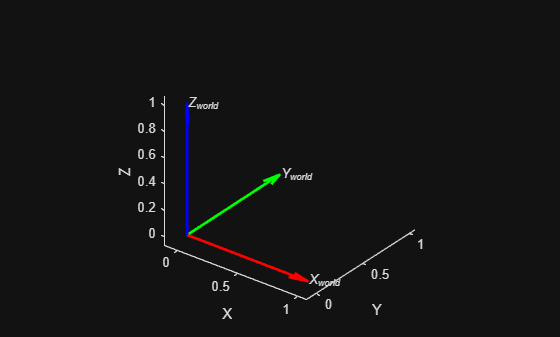

figure
axes( 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
plotframe( 'LabelBasis', true, ...
    'Labels', {'X_{world}','Y_{world}','Z_{world}'}, ...
    'TextProperties', {'FontAngle','italic'} )
xlabel( 'X' ), ylabel( 'Y' ), zlabel( 'Z' )
axis padded

## Example 2

Plot a coordinate frame with a random position and orientation. Plot in the axes specified, with equal data unit lengths along each axis, instead of the current axes. Each basis vector is drawn with a different length, e.g., representing the Cartesian components of a force.

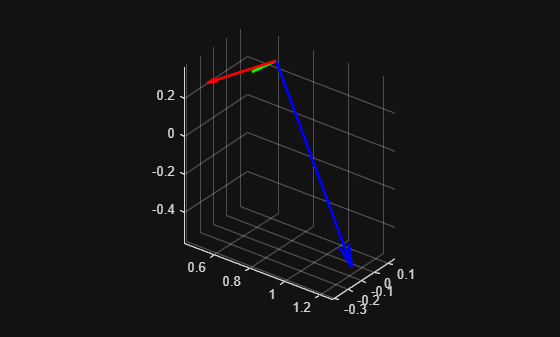

f = figure;
ax = axes( f, 'DataAspectRatio', [1 1 1], 'View', [37.5 30] );
plotframe( quat2rotm( randrot ), rand( 1, 3 ), [0.4 0.2 1], ...
    'Parent', ax )
grid( ax, 'on' )
axis( ax, 'padded' )

## Example 3

Plot a coordinate frame with styling for the basis vectors. In this color format, each row represents an RGB color for the X, Y, and Z components of the frame respectively.

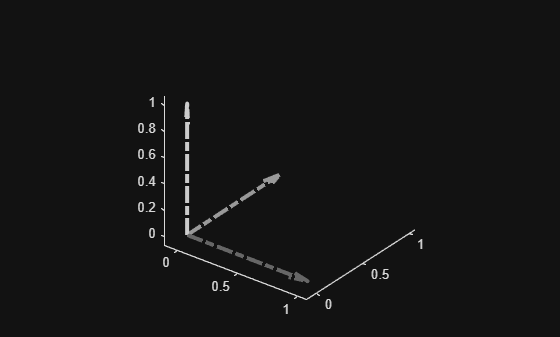

f = figure;
axes( f, 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
plotframe( 'BasisColors', [.4 .4 .4; .6 .6 .6; .8 .8 .8], ...
    'LineStyle', '-.', 'LineWidth', 3 )
axis padded

## Example 4

Plot a coordinate frame where the basis vectors cross at their center, i.e., showing both positive and negative values, and place a black marker at the frame origin.

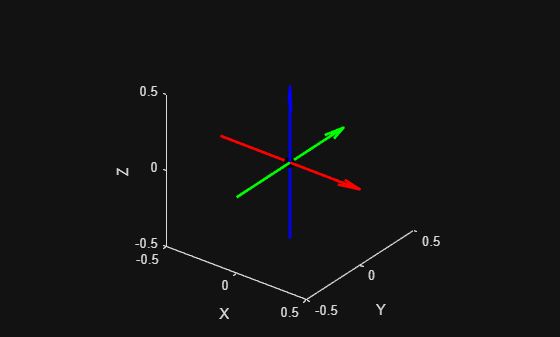

f = figure;
axes( f, 'DataAspectRatio', [1 1 1], 'View', [37.5 30] )
plotframe( 'Alignment', 'center', 'Marker', 'o', 'MarkerSize', 6, ...
    'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k' )
xlabel( 'X' ), ylabel( 'Y' ), zlabel( 'Z' )

## Example 5

Animate a rotating coordinate frame. Update the plot at each frame by passing the plot handles, `hg`, to the `UpdateFrame` argument.

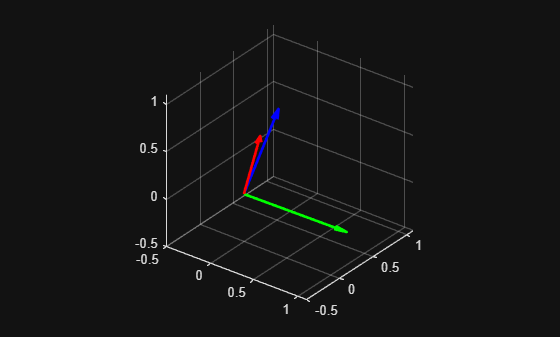

f = figure;
ax = axes( f, 'DataAspectRatio', [1 1 1], 'View', [37.5 30], ...
    'XLim', [-.5 1.1], 'YLim', [-.5 1.1], 'ZLim', [-.5 1.1], ...
    'XGrid', 'on', 'YGrid', 'on', 'ZGrid', 'on' );
hg = plotframe( 'Parent', ax );
rotation = 0;
while isgraphics( f )
    tformMatrix = makehgtform( 'axisrotate', [1 1 1], rotation );
    plotframe( tformMatrix(1:3,1:3), 'UpdateFrame', hg )
    drawnow
    rotation = rem( rotation + 0.04, 2 * pi );
end